## Dubins Path Computation

Helper script to compute shortest dubin's path. Define the test input.

startPose = [1, 2, pi/4];
goalPose = [0, -1, 0];

### This is showing the matlab's Dubin functionality (from robotics toolbox) - used as a reference to validate our implementation.

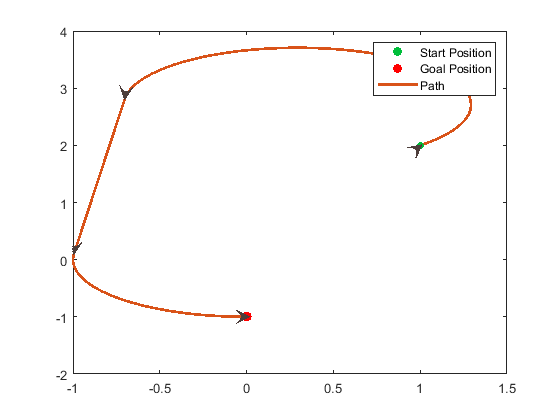

conn = robotics.DubinsConnection;
conn.MinTurningRadius = 1;
pathCalculator = connect(conn,startPose, goalPose);
pathSeg = pathCalculator{1};
show(pathSeg);

fprintf('path : %s\n', pathSeg.MotionLengths);

path : 3.819216e+00
path : 2.722905e+00
path : 1.678571e+00


fprintf('optimalMode : %s\n', strjoin(pathSeg.MotionTypes));

optimalMode : L S L


fprintf('optimalCost : %s\n', pathSeg.Length);

optimalCost : 8.220692e+00


### This is from our implementation. The values shown here should match the values shown above.

[motion_lengths, motion_types, optimalDistance, path] = computeDubinsPath(startPose, goalPose, 1);
fprintf('path : %s\n', motion_lengths);

path : 3.819216e+00
path : 2.722905e+00
path : 1.678571e+00


fprintf('optimalMode : %s\n', motion_types);

optimalMode : LSL


fprintf('optimalCost : %s\n', optimalDistance);

optimalCost : 8.220692e+00


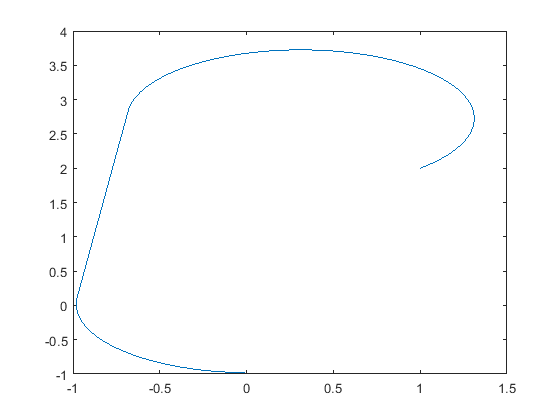

figure
plot(path(:, 1), path(:, 2))

### This is interpolation from existing matlab classes...

  % Create a connection mechanism object
  turningRadius         = 1;
  numInterpolationSteps = 20;
  connectionDistance    = 10;

  connMech = matlabshared.planning.internal.DubinsConnectionMechanism;
  connMech.TurningRadius      = turningRadius;
  connMech.NumSteps           = numInterpolationSteps;
  connMech.ConnectionDistance = connectionDistance;

  % Find the Dubins distance between two poses
  d = connMech.distance(startPose, goalPose);

  % Find wayposes between two poses along Dubins curve.
  poses = connMech.interpolate(startPose, goalPose);
